clc
clear
close all

% 参数输入
ms = 100;
mu = 1;
cs = 10;
ks = 10;
ku = 30;

M = [ms 0;0 mu];
C = [cs -cs;-cs cs];
K = [ks -ks;-ks ks+ku];
Y = [0;ku];

invM = inv(M);

options=simset('Srcworkspace','current');
out=sim('P1_son.slx',[0,10]);

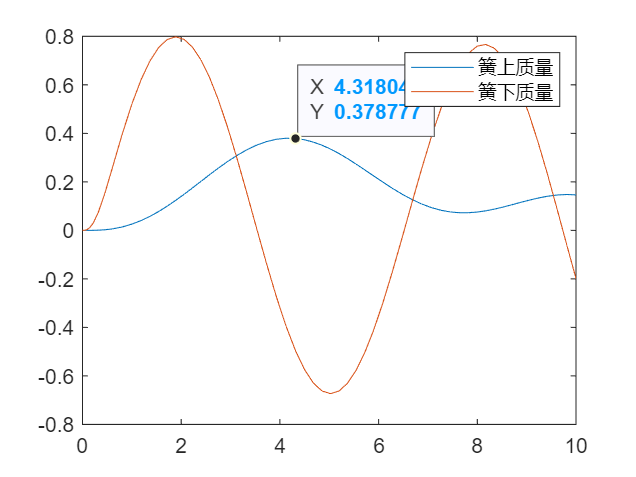

t  = out.simout.Time;
xs = out.simout.Data(:,1);
xu = out.simout.Data(:,2);

plot(t,xs,t,xu);
legend('簧上质量','簧下质量')